% 아래와 같은 분포를 갖는 독립적인 n개의 random variables의 합으로 
% 새로운 r.v.을 생성하여 central limit theorem 확인 (새로운 r.v.의 개수= 10^7)
% Uniform Distribution (0 ≤ x ≤ 1)
% (a) n = 3      (b) n = 6      (c) n = 12      (d) n = 20
% 0부터 1사이에서 uniform distribution을 갖는 n개의 r.v.들의 합으로 새로운 r.v.을 생성한다.

## n = 3

sgtitle('autocorrealation')
arr1 = zeros(1,10^7);
for cnt = 1:3
    for i = 1:10^7
        arr1(i) = arr1(i) + rand();
    end
end

m1 = mean(arr1); v1 = var(arr1);
std1 = (arr1-m1).*(1/sqrt(v1))

std1 =     1.8926    0.6303   -2.7955   -0.7272    0.4152    0.2597   -0.9593    1.2348    0.8956   -0.6925   -0.9571   -0.7351    1.6988   -1.3595   -1.9943    0.3407    1.8434    1.5722    0.0554    0.9499    0.2390    0.6912    0.9771   -1.4831    0.9563   -0.1253   -0.4994   -0.5634    1.0204   -0.3072    0.1013    0.6875    0.2836    0.5502   -0.8765   -1.3112    0.6455    0.4668   -0.2387   -1.7236    0.1433   -0.5013   -2.0540   -0.8904    0.8103    2.0192   -0.6251    1.9524   -0.8411   -0.5318


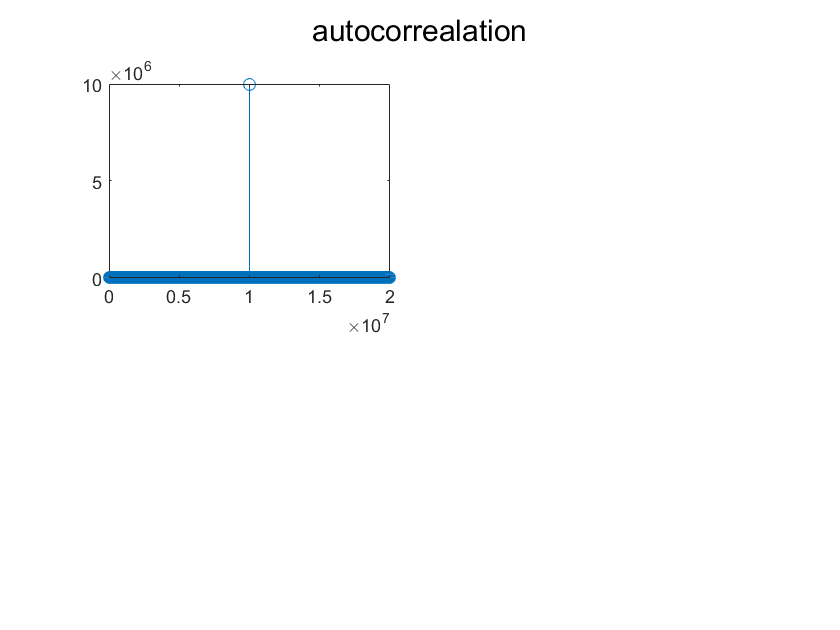

m1 = round(mean(std1),2); v1 = round(var(std1),2);
subplot(2,2,1)
stem(xcorr(std1))

% histogram(arr1) <- matlab doesn't recommand it

## n = 6

arr2 = zeros(1,10^7);
for cnt = 1:6
    for i = 1:10^7
        arr2(i) = arr2(i) + rand();
    end
end

m2 = mean(arr2); v2 = var(arr2);
std2 = (arr2 - m2).*(1/sqrt(v2))

std2 =    -0.6450    1.1069   -0.0529   -0.1109   -0.8021   -1.1591    1.2787    0.9610   -0.3780    1.2953    0.4912    0.5561   -0.7807   -0.0551    0.0213    0.1672    1.0181   -1.5159    0.4441    0.0304    0.9223   -1.4465   -0.1246   -0.2323    0.4611   -0.2507    0.6477   -0.7852   -0.9428   -0.1827   -0.7988   -0.3551   -0.1199   -0.2078    0.7505    1.0545   -1.0386    0.2855    1.3040   -0.4156    0.9543    0.3685   -1.0531   -0.1842    0.3926    0.9232    1.1444    0.6921   -0.5096   -1.4450


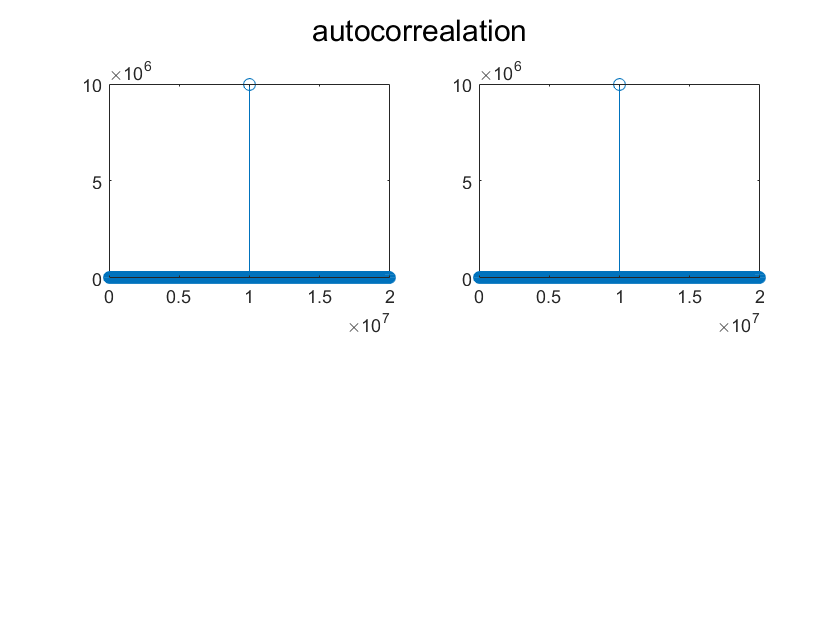

m2 = round(mean(std2),2); v2 = round(var(std2),2);
subplot(2,2,2)
stem(xcorr(std2))

## n = 12

arr3 = zeros(1,10^7);
for cnt = 1:12
    for i = 1:10^7
        arr3(i) = arr3(i) + rand();
    end
end
m3 = mean(arr3); v3 = var(arr3);
std3 = (arr3 - m3).*(1/sqrt(v3))

std3 =    -1.0430   -0.6139   -1.0192    0.6967   -1.4524   -1.8362   -0.4535   -0.4935    0.5735    0.1541    2.4221   -0.9350   -0.8750   -2.8008   -0.3076    0.3199    0.1044   -0.4268    1.4243   -0.0416   -1.0735   -0.0675    0.2395   -0.5669   -2.0937    0.0152   -1.2932   -2.9409   -1.8466    1.3673   -2.2190   -0.9669    0.5949    0.6417   -0.5157    0.3144    0.0508   -0.4858    0.1931    1.8292   -1.3951    1.2418   -0.1901   -0.4167   -0.7113    0.7428    0.7221    1.6688   -0.8526    1.7510


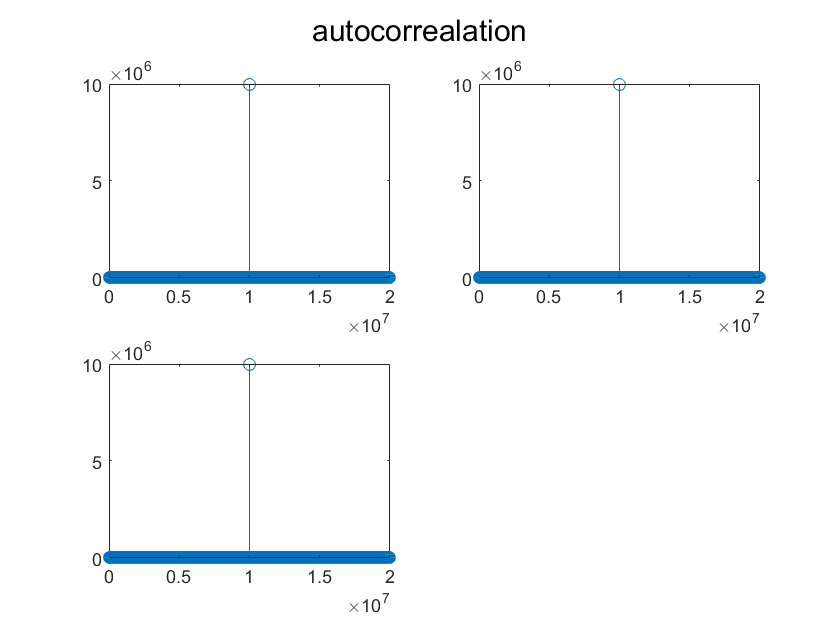

m3 = round(mean(std3),2); v3 = round(var(std3),2);
subplot(2,2,3)
stem(xcorr(std3))

## n = 20

arr4 = zeros(1,10^7);
for cnt = 1:20
    for i = 1:10^7
        arr4(i) = arr4(i) + rand();
    end
end
m4 = mean(arr4); v4 = var(arr4);
std4 = (arr4 - m4).*(1/sqrt(v4))

std4 =     0.9730    1.3805   -1.2045    0.0514   -0.8660   -1.4317   -0.3729    1.1025   -1.2794   -0.9137    1.3359   -2.0171    1.2037   -2.0336   -1.5257    1.1336    0.2147   -1.4068    0.1665    1.3611    1.1964   -1.3885   -0.0278   -0.1335    0.8080    1.5206    0.0422    0.7748    0.5106    0.3257    1.3171    0.6981    0.0649    0.1146   -0.7321    0.1868    1.0107    0.3613   -0.6525   -1.1374   -0.0915   -0.4248   -0.4299   -1.0858    0.9470   -0.2338    0.7760    0.1961    1.2182    1.0425


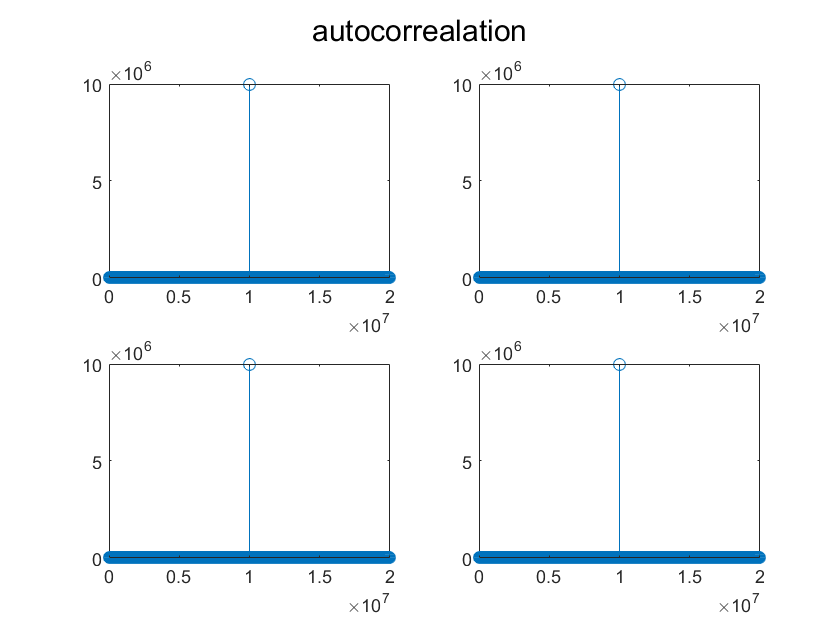

m4 = round(mean(std4),2); v4 = round(var(std4),2);
subplot(2,2,4)
stem(xcorr(std4))